clc; clear;
N = 10000;
net = IzhikevichNetwork(N);


g = net.w; Ex_mask = 1:net.Ne; Inh_mask = net.Ne+1:net.N;
g_ee = g(Ex_mask, Ex_mask);
g_ei = g(Ex_mask, Inh_mask);
g_ie = g(Inh_mask, Ex_mask);

% weights
g_ee = g_ee(net.Adjacency_matrix(Ex_mask, Ex_mask));
g_ei = g_ei(net.Adjacency_matrix(Ex_mask, Inh_mask));
g_ie = g_ie(net.Adjacency_matrix(Inh_mask, Ex_mask));

% degrees
k_ex_ex = sum(net.Adjacency_matrix(Ex_mask, Ex_mask), 1);
k_ex_inh = sum(net.Adjacency_matrix(Ex_mask, Inh_mask), 1);
k_inh_ex = sum(net.Adjacency_matrix(Inh_mask, Ex_mask), 1);

## Initial Weights Distribution

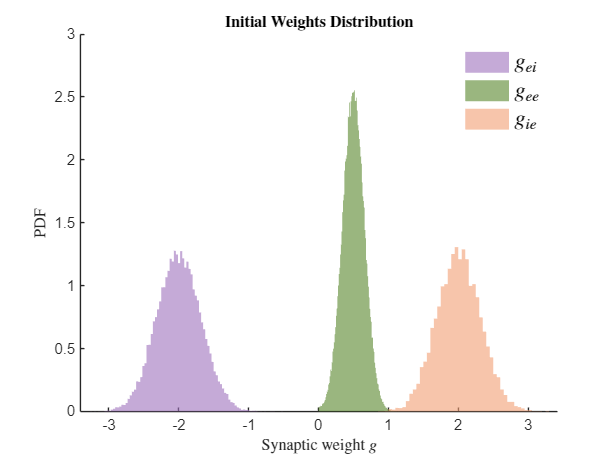

figure('Color', 'white'); hold on;
histogram(g_ei, EdgeColor="none", FaceColor=[160, 113, 190]/256, Normalization="pdf", DisplayName='$g_{ei}$');
histogram(g_ee, EdgeColor="none", FaceColor=[86, 135, 41]/256, Normalization="pdf", DisplayName='$g_{ee}$');
histogram(g_ie, EdgeColor="none", FaceColor=[243, 159, 115]/256, Normalization="pdf", DisplayName='$g_{ie}$');
 
legend('Interpreter','latex', 'FontSize', 15, 'Box','off')
xlabel("Synaptic weight $g$", 'Interpreter', 'latex');
ylabel("PDF", 'Interpreter', 'latex');
title("\textbf{Initial Weights Distribution}", 'Interpreter','latex')
print(gcf, "InitialWeights", '-dpng', '-r300')

## Degree Distribution

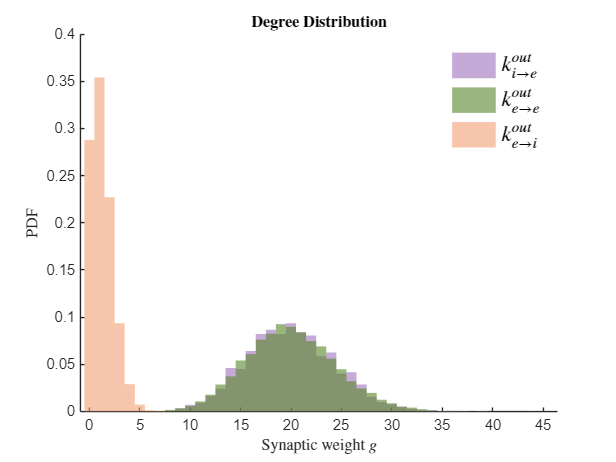

figure('Color','white'); hold on;
histogram(k_ex_inh, EdgeColor="none", FaceColor=[160, 113, 190]/256, Normalization="pdf", DisplayName='$k_{i \rightarrow e}^{out}$');
histogram(k_ex_ex, EdgeColor="none", FaceColor=[86, 135, 41]/256, Normalization="pdf", DisplayName='$k_{e \rightarrow e}^{out}$');
histogram(k_inh_ex, EdgeColor="none", FaceColor=[243, 159, 115]/256, Normalization="pdf", DisplayName='$k_{e \rightarrow i}^{out}$');
 
legend('Interpreter','latex', 'FontSize', 15, 'Box','off')
xlabel("Synaptic weight $g$", 'Interpreter', 'latex');
ylabel("PDF", 'Interpreter', 'latex');
title("\textbf{Degree Distribution}", 'Interpreter','latex')
print(gcf, "Degree Distribution", '-dpng', '-r300')